# Incapacity Episode Analysis (2022-now)

## Data Selection

trailingXMonths = 12; % Trailing X Months (TXM) analysis will be computed below, for specified X months (which are valid/available)
monthsValidDict = dictionary(2022:2023,{7:10,[2 3 4 5 6 7]}); % hard-coded months with valid (sufficient) data


Identify range of days included within Trailing X Months window:

endDate = datetime("now");
startDate = endDate - calmonths(trailingXMonths-1);

daysStudy_ = startDate:endDate;

Remove days from months without sufficient data for monthly viz/stats: 

daysStudy = daysStudy_;
idx = numel(daysStudy);
for date = daysStudy_(end):-1:daysStudy_(1)
    if ~ismember(month(date), monthsValidDict{year(date)}) %check if month has valid data
        daysStudy(idx) = [];
    end
    idx = idx - 1;
end

Create equal-length month/year arrays identifying trailing X months here: 

%monthsStudy = monthsValidDict{yearStudy}; % use all valid months by default
[monthsTXM, idx] = unique(month(daysStudy),'stable');
yearsTXM = year(daysStudy(idx));
numMonthsStudy = numel(monthsTXM);


## Data Access & Cleaning

#### Read years of interest from workbook

currentYear = year(datetime("now"));

setenv('AWS_DEFAULT_REGION','us-east-2');
readYearFcn = @(yearVal) readtable('s3://vijayiyer05-me-health-metrics/Episodes.xlsx','Sheet',string(yearVal),'TextType','string');

TCurrYear = readYearFcn(currentYear);

TPriorYear = readYearFcn(currentYear-1);


T = [TPriorYear; TCurrYear]; 
T = sortrows(T,"Timestamp","ascend");

#### Clean and annotate table for downstream analysis

% Crate study table with missing durations removed 
TAnnotated = T(~ismissing(T.Duration),:);

% Convert Duration variable to MATLAB duration type
durationTimestamp = datetime(datevec(TAnnotated.Duration)); %represent duration variable as a datetime timestamp
referenceTimestamp = datetime(zeros(1,6)); % start of day on first date

durationVar = durationTimestamp - referenceTimestamp;
TAnnotated.Duration = durationVar; 

% No longer needed (done day-wise above)
% Remove months not under study 
%TAnnotated = TAnnotated(ismember(month(TAnnotated.Date),monthsTXM),:);

% Add categorical month variable
monthVec = categorical(datetime(year(TAnnotated.Date),month(TAnnotated.Date),1,'Format','MMMM yyyy'),'Ordinal',true); %awkward: lots of steps from month numbers to month categorical
TAnnotated = addvars(TAnnotated,monthVec,'NewVariableNames',"Month");
TAnnotated.Month = removecats(TAnnotated.Month);


#### Create Trailing X Month table 

TTrailingX = TAnnotated(1,:);  
TTrailingX(1,:) = [];
for idx = 1:numel(monthsTXM)
    m = monthsTXM(idx);
    y = yearsTXM(idx);
    TTrailingX = [TTrailingX;TAnnotated(month(TAnnotated.Date) == m & year(TAnnotated.Date) == y,:)]; %#ok<AGROW> 
end
TTrailingX.Month = removecats(TTrailingX.Month);

## Trailing X Months Visualization

#### Visualize episodes across trailing X months with a swarm chart

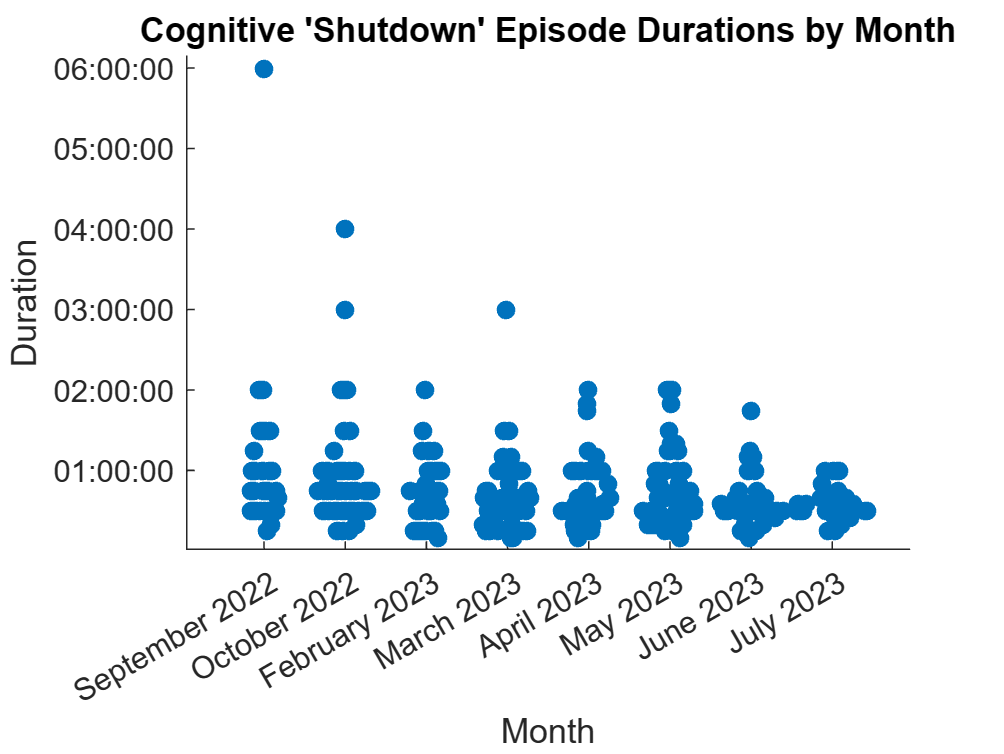

% durationsByMonth = cell(1,numMonthsStudy);
% TSwarm = TStudy(1,:); 
% TSwarm(1,:) = [];
% for idx = 1:numel(monthsStudy)
%     m = monthsStudy(idx);
%     y = yearsStudy(idx);
%     TSwarm = [TSwarm;TStudy(month(TStudy.Date) == m & year(TStudy.Date) == y,:)]; %#ok<AGROW> 
% end
swarmchart(TTrailingX,"Month","Duration","filled");
title("Cognitive 'Shutdown' Episode Durations by Month");

#### Compute summary statistics of episodes during each month

[medianDuration,meanDuration, numEpisodesByMonth, numDaysTracked] = deal(zeros(numel(monthsTXM),1));

for idx = 1:numel(monthsTXM)
    m = monthsTXM(idx);
    y = yearsTXM(idx);

    TCurrMonth = TTrailingX(month(TTrailingX.Date) == m & year(TTrailingX.Date) == y,:);

    summaryStruct = summary(TCurrMonth);
    s = summaryStruct.Duration;
    medianDuration(idx) = minutes(s.Median);
    numEpisodesByMonth(idx) = prod(s.Size);

    numDaysTracked(idx) = days(summaryStruct.Date.Max - summaryStruct.Date.Min) + 1;

    meanDuration(idx) = mean(minutes(TCurrMonth.Duration));
    
    assert(medianDuration(idx) == median(minutes(TCurrMonth.Duration)));
end

#### Plot summary statistics of episodes during each month

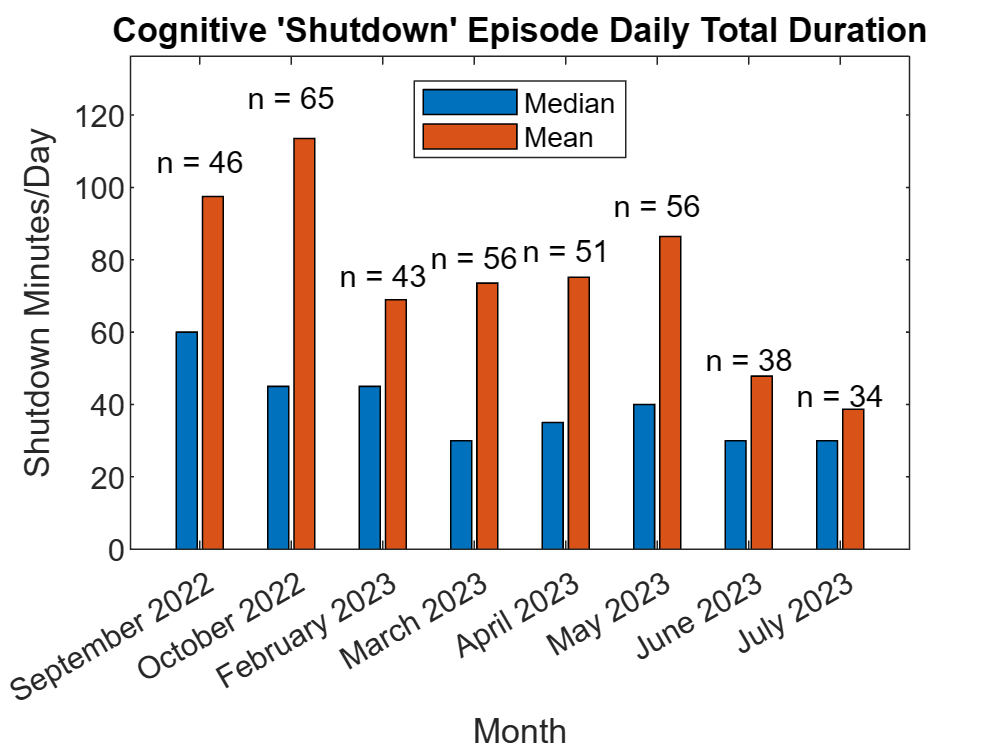

daysInMonth = zeros(numMonthsStudy,1);

% Determine per-month normalization factor for each month
for idx = 1:numMonthsStudy    
    if month(datetime("now")) == monthsTXM(idx) % mid-month analysis
        daysInMonth(idx) = numDaysTracked(idx);
    else
        calendar_ = calendar(yearsTXM(idx),monthsTXM(idx));
        daysInMonth(idx) = max(calendar_,[],'all');
    end
end


% Renormalize mean incapacity time by days in month 
dailyIncapacityByMonth = numEpisodesByMonth.*meanDuration./daysInMonth;

% Plot bar chart & add num episodes label to each month
monthLabels = unique(TTrailingX.Month,'stable');
bar(monthLabels,[medianDuration dailyIncapacityByMonth]);
for idx = 1:numMonthsStudy
    text(monthLabels(idx),dailyIncapacityByMonth(idx)*1.1,"n = " + string(numEpisodesByMonth(idx)),'HorizontalAlignment','center');
end

ylim([0 max(dailyIncapacityByMonth*1.2)]);
xlabel("Month");
ylabel("Shutdown Minutes/Day");
title("Cognitive 'Shutdown' Episode Daily Total Duration")
legend(["Median" "Mean"],"Location","north");

## Last Month Visualization

#### Visualize episodes during a specific month (last month by default)

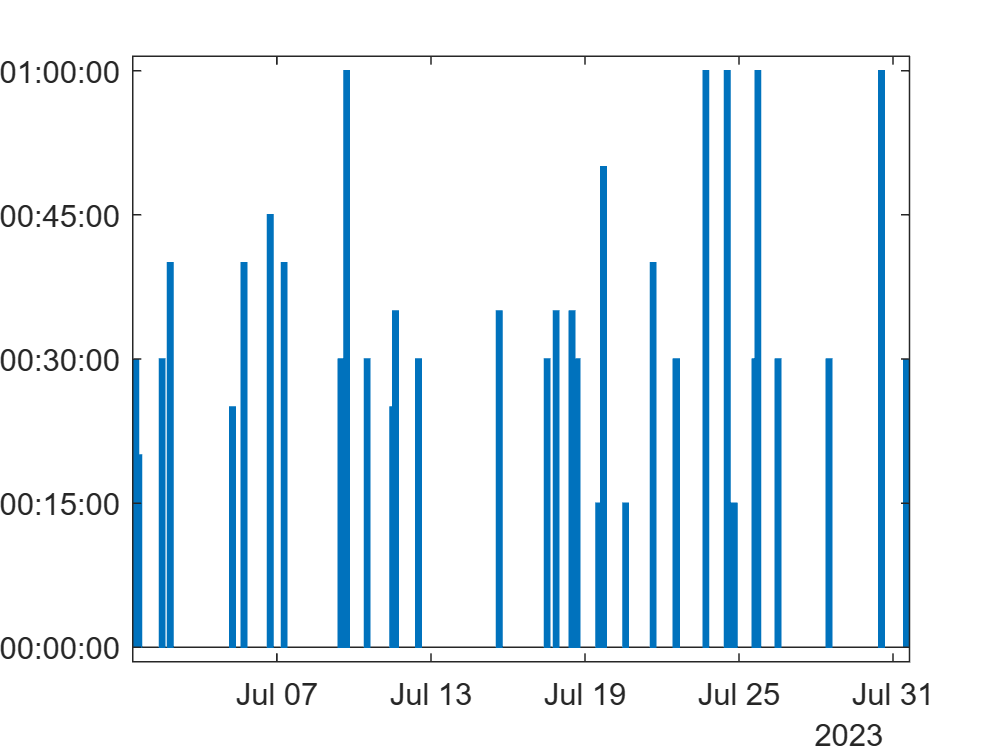

%monthViz =7;
monthViz = monthsTXM(end); % most recent month; comment out to select with control above
yearViz = yearsTXM(end);

TCurrMonth = TTrailingX(month(TTrailingX.Date) == monthViz & year(TTrailingX.Date) == yearViz,:);

hChart = bar(TCurrMonth.Timestamp,TCurrMonth.Duration,'BarWidth',10);
hChart.EdgeColor = hChart.FaceColor;